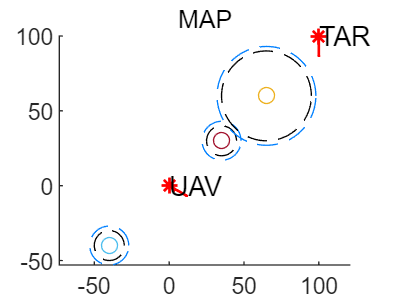

clear all
%% 定义函数输入
Start_Point = [0,0,-pi/6];
End_Point = [100,100,-pi/2];%[x,y,角度]
r=15;%最小转弯半径

% r_s=15;
% r_e=r_s;

sure=3;%保证安全的预留距离
% R=10+sure;

Stepsize=0.01;%路径的生成间隔
% Avoid_Center = [35,30;
%                 60,50;];
obs=[35,30,10+sure;
     65,60,30+sure;
     -40,-40,10+sure];%[x,y,障碍物的半径R]

figure(1)
Draw_map(Start_Point,End_Point,obs,sure);%绘制地图

hold off

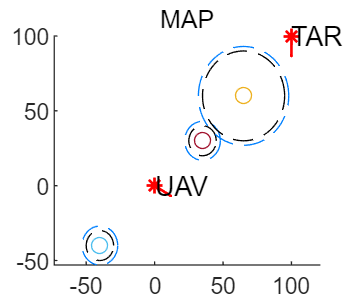

%A*算法开始，产生初始路径
figure(2)
Draw_map(Start_Point,End_Point,obs,sure);

[param_all_start,param_best_start] = Dubins_no_obs(Start_Point, End_Point,r,r,Stepsize);
%%判断所有的初始路径是否不碰撞
flag_all=zeros(1,length(obs(:,1)));%%障碍物m个=>m列
for i=1:4
    flag_safe=if_safe(param_all_start(i).path,obs,1,3);
    flag_all(i,:)=flag_safe;
end
%%选出碰撞的障碍物n个（及其路径）
[pah_num, obs_num] = find(flag_all == 0);%%第pah_num行，第obs_num列为0
[obs_to_avoid, ~, ~] = unique(obs_num);
%%生成避障路线n(转弯半径只有1种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]
for i=1:length(obs_to_avoid)
    [param_all{i},param_best{i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
%     [param_all{2,i},param_best{2,i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
end
%%param_all=>k列=K个障碍物==>每一个cell是一个1*4（4种路径）的结构体

% node_now=[Start_Point,]

%%检查避障路线的from_path=1,to_path=2是否碰撞
% %（从当前节点到下一节点）
flag_all=zeros(1,length(obs(:,1)));
for j=1:length(obs_to_avoid)%%针对每个障碍物
    for i=1:4
        flag_safe=if_safe(param_all{j}(i).path,obs,1,2);
        flag_all((i+4*(j-1)),:)=flag_safe;
    end
end

path_safe_flag=[];
for i = 1:length(flag_all(:,1))
    if all(flag_all(i, :) == 1)
        path_safe_flag=[path_safe_flag,i];%某行全1=>该路径安全
    end
end
%(路径数=需要躲避障碍物数*4)*障碍物数


% path_safe_flag=path_safe_flag;

% flag_all_2=zeros(1,length(obs(:,1)));
% for j=1:length(obs_to_avoid)
%     for i=1:4
%         flag_safe=if_safe(param_all{2,j}(i).path,obs,1,2);
%         flag_all_2((i+4*(j-1)),:)=flag_safe;
%     end
% end
% for i = 1:length(flag_all_1(:,1))
%     if all(flag_all_1(i, :) == 1)
%         path_safe(2,:)=[path_safe(2,:),i];
%     end
% end

%%选择不碰撞的路径，g=到起点的距离=path.1+path.2,h=直线距离？
%%节点[点的位置(2个=出发圆+障碍圆切入)，方向(2个)，f,g,path(2个=弧度+直线)]
for i=1:length(path_safe_flag)
    param=param_all{ceil(path_safe_flag(i)/4)}(path_safe_flag(i)-4*(ceil(path_safe_flag(i)/4)-1));
    %%索引路径参数第几（初始半径）行第几（躲避障碍圆）个，具体第几个路径
    node.point=param.point(:,2:3);
    node.vtheta=param.vtheta(2:3);
    node.g=sum(param.length(1:2));
    node.f=node.g+obtain_h(node.point(:,2)',End_Point);
    node.path{1}=param.path{1};
    node.path{2}=param.path{2};
    node.R=param.R;
    node.obs=param.center(:,2);
    open_f=[open_f,node.f]
    open{end+1}=node;
end

函数或变量 'open_f' 无法识别。


%%选择最短节点
% min_f=inf;
% for i=1:length(open)
%     if open{i}.f<min_f
%         min_f=opn{i}.f
%         flag_min=i;
%     end
% end

flag_min=find(open_d==min(open_f))

%%移除open，加入close
close{end+1}=open{flag_min}
open{flag_min}={}
open_f(flag_min)=[]

%%生成无碰撞路径2(半径不同)*4

[param_all_obs{1},param_obs{1}] = Dubins_no_obs(Start_Point, End_Point,r,r,Stepsize);
[param_all_obs{2},param_obs{2}] = Dubins_no_obs(Start_Point, End_Point,open{flag_min}.R,r,Stepsize);
%%判断所有的初始路径是否不碰撞(和自己碰撞直接排除)=>直接生成

for j=1:2%%针对每个障碍物
    for i=1:4
        flag_safe=if_safe(param_all_obs{j}(i).path,obs,1,2);
        flag_all((i+4*(j-1)),:)=flag_safe;
    end
end

[pah_num, obs_num] = find(flag_all == 0);
[obs_to_avoid, ~, ~] = unique(obs_num);
%%选出碰撞的障碍物(排除和自己的转弯圆碰撞)n个（及其路径）
for i=length(obs_to_avoid)
    if isequal(obs(i,1:2),open{flag_min}.center')
        flag_all(:,i)=1
    end
end

%%%%%%%%%%%%%%%%%%确定具体的躲避障碍

%%生成避障路线n(转弯半径2种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]
for i=1:length(obs_to_avoid)
    [param_all{1,i},param_best{1,i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
end
%    



Draw_path(param_best{1},sure,1,2)
hold off